%% Satellite Collision Risk Simulation
% Simulates a geostationary satellite and debris in a perturbed orbit

clc; clear; close all;

% Earth Constants
mu_earth = 3.986004418e14;     % Earth's gravitational parameter (m³/s²)
R_earth = 6371e3;              % Earth radius (m)

%% Orbital Parameters
% Satellite (Geostationary)
alt_sat = 35800e3;             % 35,800 km altitude
a_sat = R_earth + alt_sat;     % Semi-major axis (m)
v_sat = sqrt(mu_earth/a_sat);  % Circular velocity (m/s)

% Debris (Slightly lower orbit)
alt_debris = alt_sat - 1
e3;   % 10 km lower than satellite
a_debris = R_earth + alt_debris;
v_debris = sqrt(mu_earth/a_debris);

%% Initial Conditions
% Satellite starts at (a_sat, 0, 0) with velocity (0, v_sat, 0)
r_sat0 = [a_sat; 0; 0];
v_sat0 = [0; v_sat; 0];

% Debris starts 50 km behind satellite in along-track direction
theta_offset = -50e3/a_sat;    % Angular offset (radians)
r_debris0 = a_debris * [cos(theta_offset); 
                             sin(theta_offset);
                             0];
v_debris0 = [-sin(theta_offset)*v_debris;
             cos(theta_offset)*v_debris;
             0];

%% Orbit Propagation
tspan = [0 4*3600]; % 4 hours simulation
initial_state = [r_sat0; v_sat0; r_debris0; v_debris0];

options = odeset('RelTol',1e-9,'AbsTol',1e-12);
[t, state] = ode45(@(t,y) orbit_equations(t,y,mu_earth), ...
                   tspan, initial_state, options);

%% Post-Processing
% Extract positions
r_sat = state(:,1:3);          % Satellite position
r_debris = state(:,7:9);       % Debris position

% Calculate relative distance
rel_distance = vecnorm(r_sat - r_debris, 2, 2);

% Find closest approach
[min_dist, idx] = min(rel_distance);
fprintf('Closest approach: %.2f km at %.1f hours\n',...
        min_dist/1e3, t(idx)/3600);

Closest approach: 48.43 km at 4.0 hours


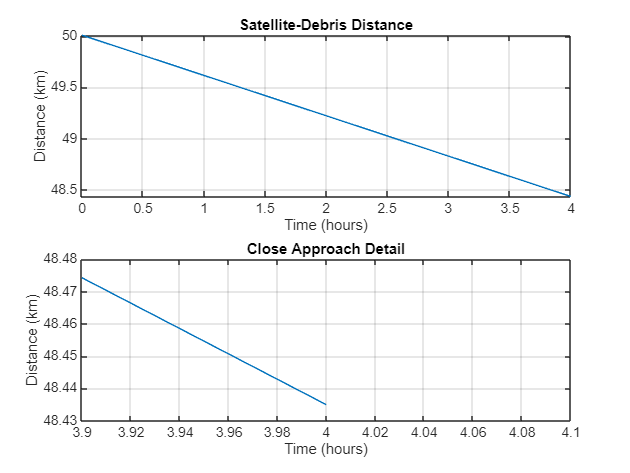


%% Visualization
figure;
subplot(2,1,1)
plot(t/3600, rel_distance/1e3)
xlabel('Time (hours)')
ylabel('Distance (km)')
title('Satellite-Debris Distance')
grid on

subplot(2,1,2)
plot(t/3600, rel_distance/1e3)
xlabel('Time (hours)')
ylabel('Distance (km)')
title('Close Approach Detail')
xlim([t(idx)/3600-0.1 t(idx)/3600+0.1])
grid on

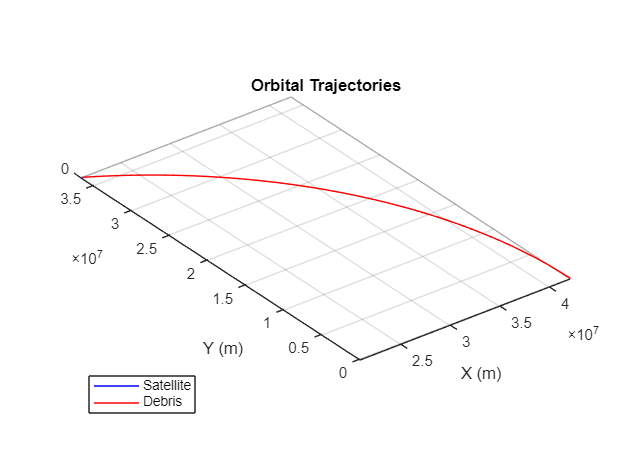


figure;
plot3(r_sat(:,1), r_sat(:,2), r_sat(:,3), 'b', ...
      r_debris(:,1), r_debris(:,2), r_debris(:,3), 'r')
axis equal
grid on
xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)')
title('Orbital Trajectories')
legend('Satellite', 'Debris', 'Location','best')


%% Differential Equations
function dy = orbit_equations(~,y,mu)
    % State vector decomposition
    r1 = y(1:3); v1 = y(4:6);
    r2 = y(7:9); v2 = y(10:12);
    
    % Satellite acceleration
    a1 = -mu*r1/norm(r1)^3;
    
    % Debris acceleration
    a2 = -mu*r2/norm(r2)^3;
    
    % State derivative
    dy = [v1; a1; v2; a2];
end